Nbits = 1e4;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

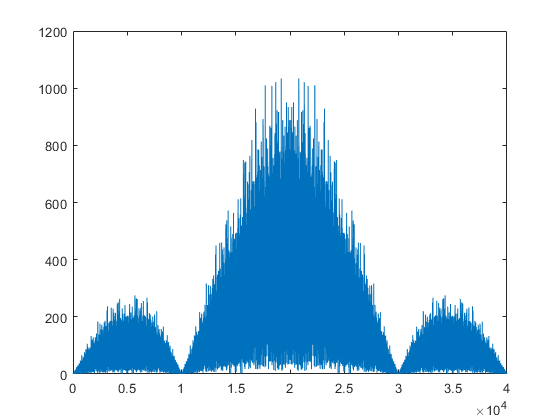

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);
%Tc=1/R_s/SpS;
d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 1;

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end

figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);

for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Scegliamo di campionare sul primo bit

    %samp_bit = 0;
    %r = zeros(Nbits, 1);
    %for a=1:Nbits
    %    r(a) = (y(a*4+samp_bit) > 0)*2-1;
    %end
    r = y(1:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

Plotting

figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

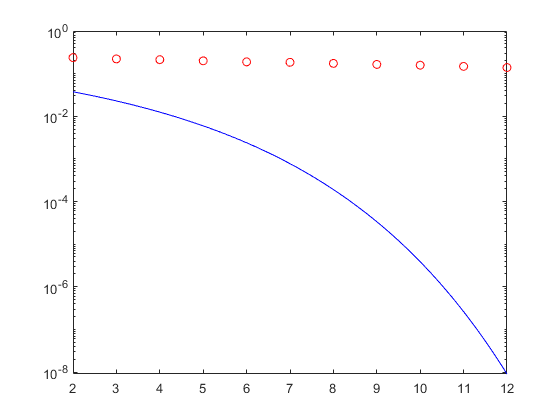

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')